clear all;

% Initialize Pluto SDR Receiver
rx = sdrrx('Pluto');

% Configure Receiver
rx.GainSource = 'AGC Slow Attack'; % Automatisk gain control
ch_size = 1e6; % Antall samples per ramme
basebandSampleRate = 10e6; % Baseband sample rate
rx.SamplesPerFrame = ch_size; % Antall samples per prosessering
rx.BasebandSampleRate = basebandSampleRate;

% Sett senterfrekvens til 800 MHz
rx.CenterFrequency = 800e6; 

% Initialize Spectrum Analyzer
spectrumAnalyzer = spectrumAnalyzer('SampleRate', basebandSampleRate, ...
    'SpectrumType', 'Power density', ...
    'Title', 'Spektrum ved 800 MHz', ...
    'SpectralAverages', 10, ...
    'PlotMaxHoldTrace', true);

% Start måling

Analyserer 800 MHz-båndet...


for i = 1:20 % Samle flere rammer for mer nøyaktig resultat
    data = rx(); % Motta IQ-data fra PlutoSDR
    spectrumAnalyzer(data); % Plot spektrum
end

## Establishing connection to hardware. This process can take several seconds.


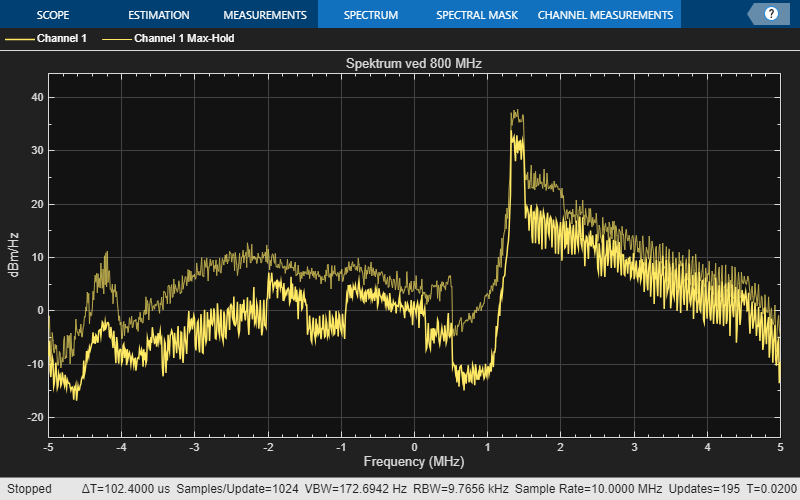


% Release resources
release(rx);
release(spectrumAnalyzer);